# Cargar información de NDVI RCAT

## Declaracion de variables sobre el área de estudio

import matlab.io.hdfeos.*

%clearvars -except area_estudio;
clear;
close all;

disp(">>> Declarando variables...ok")

>>> Declarando variables...ok



%directorio de datos
dir_data = "E:\DATA\";
producto = 'MOD13Q1';
archivo_kml = "Naranja_3";
% archivo_kml = "Selva";
% archivo_kml = "Bosque";

## **Obtener lista de archivos del producto**

info_hdf = f_infohdfs2table(dir_data,producto);

>>>>> Obteniendo información de archivos sobre fechas ... 
>>>>> Analizando 1084 archivos


[num_registros_totales,~] = size(info_hdf);

[lon_mapa,lat_mapa] = f_get_map_window(dir_data,archivo_kml,0.1);

% El ultimo parametro es el margen o umbral requerido para los datos NDVI
[coord_1k_v6_inicio,coord_1k_v6_tam,coord_1k_v7_inicio,coord_1k_v7_tam,ndvi_tam]...
    = f_get_coordinates(dir_data,archivo_kml,producto,info_hdf,0.28);

>>>>> Obteniendo la zona de estudio
E:\DATA\MOD13Q1\061\*.hdf
>>>>> Analizando 1084 archivos


## Obtener matrices de latitud longitud

% Datos sin el disco duro
% info_hdf = f_infohdfs2table(dir_data,"MOD13Q1");
% Datos con el disco duro
% info_hdf = f_infohdfs2table("G:\DATA\","MOD13Q1");

if (num_registros_totales > 0)
    [lat,lon,ndvi]=f_get_latlon(info_hdf,coord_1k_v6_inicio,coord_1k_v6_tam,coord_1k_v7_inicio,coord_1k_v7_tam);
end

>>>>> Obteniendo latitud y longitud


## **Crear el área de estudio**

% crear matriz de 0 y 1 que delimitan el área de estudio
ae = exist("study_area","var");
if ae == 0  %% no existe
    ae = exist("study_area_"+archivo_kml+"_"+producto+".mat","file");
    if ae == 2
        disp(">>> Cargando área de estudio");
        load ("study_area_"+archivo_kml+"_"+producto);

        if( numel(study_area) ~= ( ndvi_tam(1)*ndvi_tam(2)) )
            disp("La variable area_estudio sera sustituida 1");
            study_area = f_create_study_area(dir_data+'KML\'+archivo_kml+'.kml',lat,lon);
            save ("study_area_"+archivo_kml+"_"+producto+".mat",'study_area');
        else
            disp(">>> Área de estudio existente 1");
        end

    else
        study_area = f_create_study_area(dir_data+'KML\'+archivo_kml+'.kml',lat,lon);
        save ("study_area_"+archivo_kml+"_"+producto+".mat",'study_area');
    end
else
    if( numel(study_area) ~= ( ndvi_tam(1)*ndvi_tam(2)) )
        disp("La variable area_estudio sera sustituida 2");
        study_area = f_create_study_area(dir_data+'KML\'+archivo_kml+'.kml',lat,lon);
        save ("study_area_"+archivo_kml+"_"+producto+".mat",'study_area');
    else
        disp(">>> Área de estudio existente 2");
    end
end

>>> Cargando área de estudio


>>> Área de estudio existente 1


Pintar NDVI

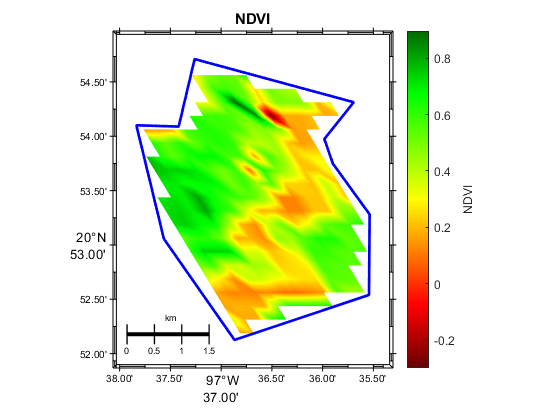

ndvi = double(ndvi) .* 0.0001;
ndvi(study_area==false)=nan;

f_draw_map(lon_mapa,lat_mapa,lon,lat,ndvi,"NDVI",[],"NDVI","NDVI");
f_draw_kml(dir_data,archivo_kml,2,'b',0);

## Leer los arreglos de datos

% Realizar la consulta de los datos que se requieren
% tmp = find(  info_hdf.anio >= 2000 &  info_hdf.anio <= 2022);
tmp = find(  info_hdf.anio == 2022);
info_consulta = info_hdf(tmp,:);

[num_registros,~] = size(info_consulta);

% arreglo 3d de ndvi por día
arr_ndvi = zeros( ndvi_tam(1),ndvi_tam(2) ,num_registros);
% arreglo 3d para la calidad del pixel
arr_ndvi_re = zeros( ndvi_tam(1),ndvi_tam(2) ,num_registros);
% arreglo 3d para pixeles de buena calidad

arr_ndvi_nan = zeros( ndvi_tam(1),ndvi_tam(2) ,num_registros);
% arreglo 3d para pixeles completos
arr_ndvi_com = zeros( ndvi_tam(1),ndvi_tam(2) ,num_registros);

bp=waitbar(0,'Obteniendo información de archivos MODIS'); 
for i=1:num_registros
    [ndvi,~,~,disponibilidad] = f_get_ndvi(info_consulta(i,:),coord_1k_v6_inicio,coord_1k_v6_tam,coord_1k_v7_inicio,coord_1k_v7_tam);

    % recortar el area de estudio
    ndvi(study_area==false)=NaN;
    disponibilidad(study_area==false)=NaN;

     %almacenar en el arreglo en 3d
    arr_ndvi(:,:,i) = ndvi;
    arr_ndvi_re(:,:,i) = disponibilidad;
 
    %barra de progreso
    waitbar(i/num_registros,bp,sprintf('Obteniendo información de archivos MODIS (%3.0f%%) ',(i/num_registros*100)));
end
close(bp); 


bp=waitbar(0,'Generando series de tiempo con interpolación'); 
for i=1:ndvi_tam(1)
     for j=1:ndvi_tam(2)
         if study_area(i,j) == true
            arr_ndvi_nan(i,j,:) = f_rm_pixel_baja_calidad(arr_ndvi(i,j,:),arr_ndvi_re(i,j,:));
            arr_ndvi_com(i,j,:) =  f_fillmissing_linear(arr_ndvi_nan(i,j,:),0);
         end

     end
     waitbar(i/ndvi_tam(1),bp,sprintf('Generando series de tiempo con interpolación (%3.0f%%) ',(i/ndvi_tam(1)*100)));
end
close (bp);


## Serie de tiempo

[y,x,~] = size(arr_ndvi);
% size(arr_ndvi)
figure;
for i=1:y
    for j=1:x
        if(study_area(i,j)==1)
            serie = reshape(arr_ndvi(i,j,:),[],1);
            plot(serie)
            ylim([0.4 1]);
            hold on
        end
    end
end
ylabel("NDVI")
xlabel("Dias")
title("NDVI","Año 2022 "+archivo_kml);
% exportgraphics(gcf,'vectorfig.png','ContentType','vector')

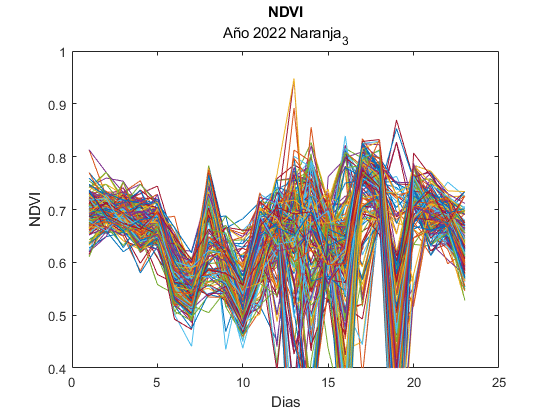

hold off